## Load Data

% Sinusoid data
load('Input_1_response.mat')
y1 = angular_velocity.data;
y2 = pendulum_angle.data;
current = dc_current.data;
u = stim_input_1';
N = size(t,2);
y = zeros(N,1);
for i = 1:N
    y((i-1)*2+1:i*2) = [y1(i); y2(i)];
end
% Step data
load('step_response.mat')
y1step = angular_velocity.data;
y2step = pendulum_angle.data;
currentstep = dc_current.data;
ustep = squeeze(step.data);
clearvars -except y y1 y2 current u t y1step y2step currentstep ustep


## Plot of everything

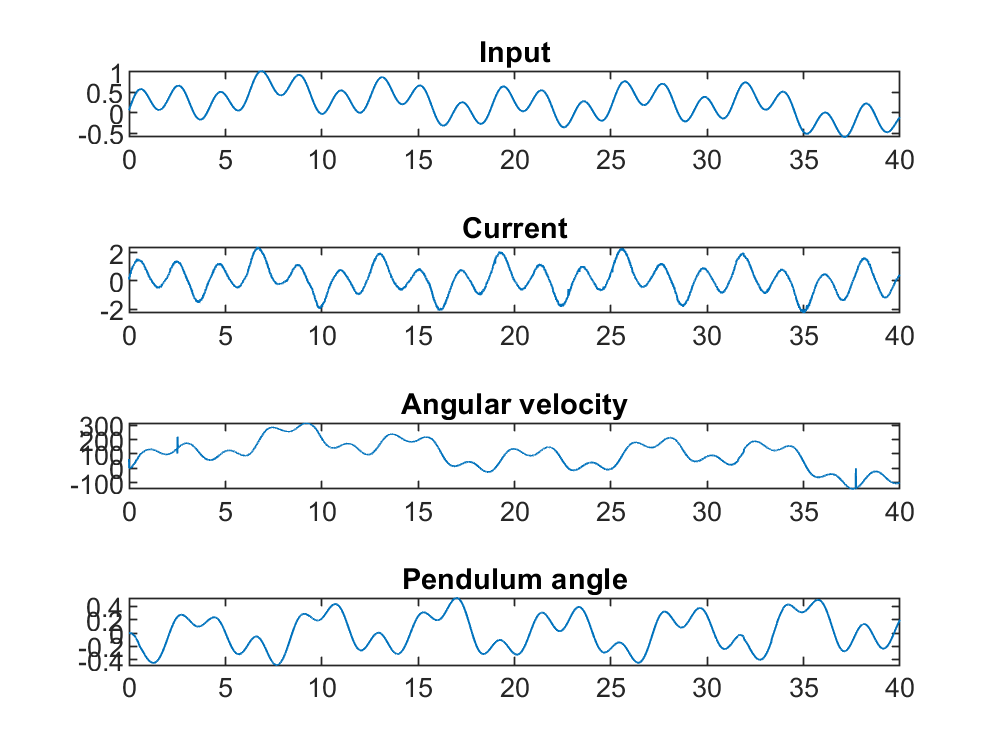

figure;
tiledlayout(4,1);
nexttile
plot(t,u);
title("Input");
nexttile;
plot(t,current);
title("Current");
nexttile;
plot(t,y1);
title("Angular velocity")
nexttile;
plot(t,y2);
title("Pendulum angle");

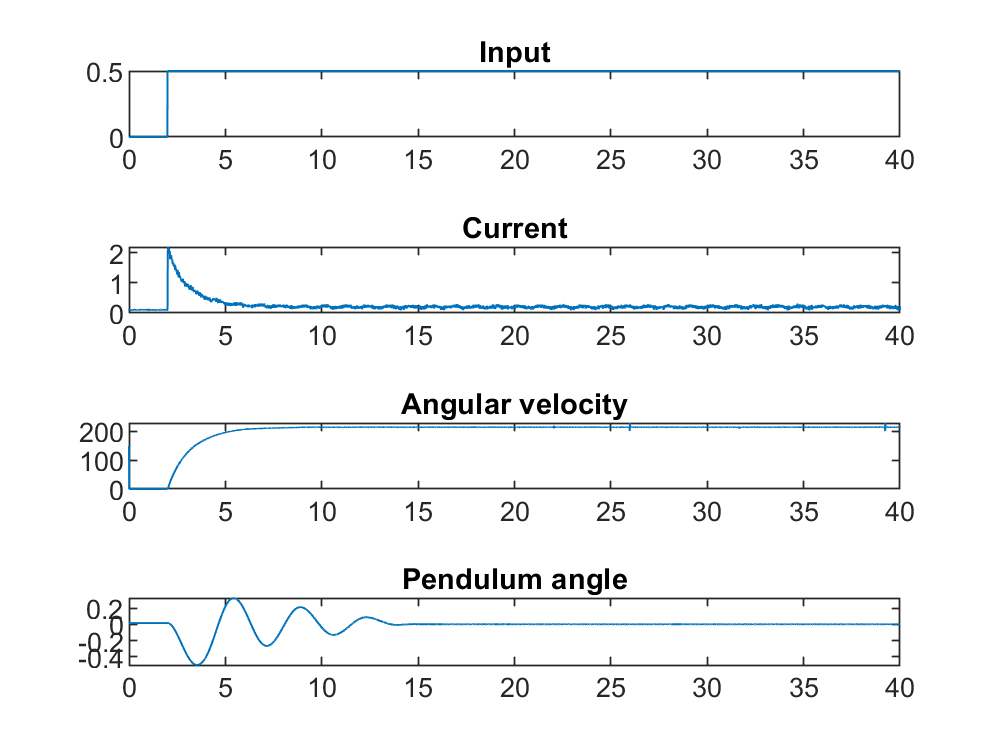


figure;
tiledlayout(4,1);
nexttile
plot(t,ustep);
title("Input");
nexttile;
plot(t,currentstep);
title("Current");
nexttile;
plot(t,y1step);
title("Angular velocity")
nexttile;
plot(t,y2step);
title("Pendulum angle");

## Apply PEM

theta0 = [1 0 0 0 1 0 0 0 1 1 0 0 1 0 0 0 1 0 0 0 0]';
theta = theta0;
lambda = 500000;
maxiter = 500;

% initialize
converged = false;
maxiter_reached = false;
iter = 1;

while ~converged && ~maxiter_reached 

    %%%%%% YOUR CODE HERE %%%%%%

    [Abar, Bbar, Cbar, D, x0] = theta2matrices(theta);
    [yhat, xhat] = simsystem_y_as_vec(Abar, Bbar, Cbar, D, x0, u);
    E = y - yhat;
    psi = psi_fun(xhat, x0, u, Abar, Cbar);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(21))\eye(21); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-3 
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   


## Evaluate

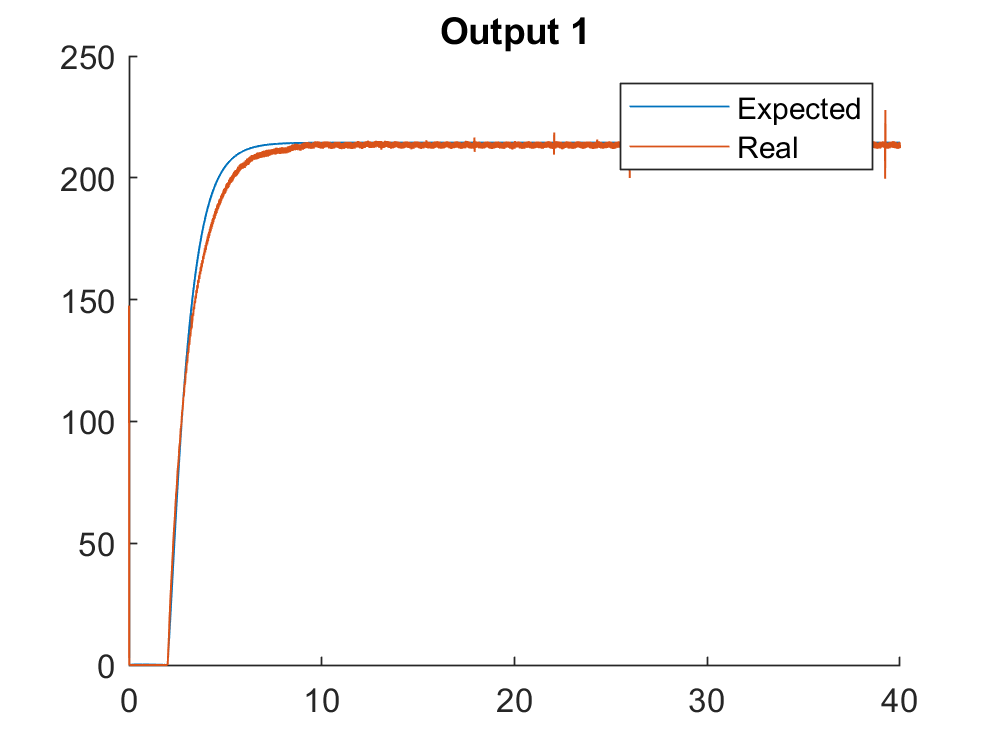

[y,x] = simsystem(Abar, Bbar, Cbar, D, x0,ustep);

figure;
hold on
plot(t,y(1,:));
plot(t,y1step);
legend("Expected", "Real");
title("Output 1");

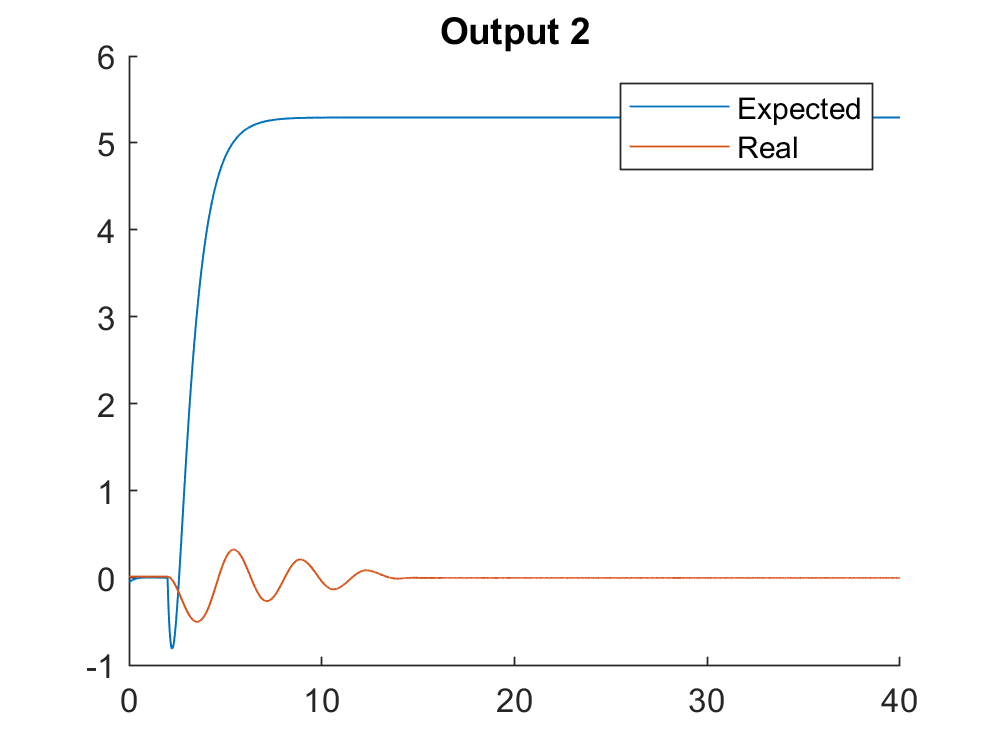


figure;
hold on
plot(t,y(2,:));
plot(t,y2step);
legend("Expected", "Real");
title("Output 2");

## PEM (functions)

function [Abar,Bbar,C,D,x0] = theta2matrices(theta)
% Converts theta into matrices for a full parameterisation with n = 3, l =
% 2
% Function INPUT
% theta     Parameter vector (vector of size: according to the realization)
%
% Function OUTPUT
% Abar      System matrix A (matrix of size n x n)
% Bbar      System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

%%%%%% YOUR CODE HERE %%%%%%
a1 = theta(1); a2 = theta(2); a3 = theta(3); a4 = theta(4);
a5 = theta(5); a6 = theta(6); a7 = theta(7); a8 = theta(8);
a9 = theta(9); b1 = theta(10); b2 = theta(11); b3 = theta(12);
c1 = theta(13); c2 = theta(14); c3 = theta(15); c4 = theta(16);
c5 = theta(17); c6 = theta(18); x0 = theta(19:21);

Abar=[a1 a2 a3; a4 a5 a6; a7 a8 a9]; 
Bbar=[b1; b2; b3]; 
C=[c1 c2 c3; c4 c5 c6]; D=[0; 0];
end

function psi = psi_fun(xhat, x0, u, Abar, Cbar)

% Dimensions
n = 3; l = 2;

% Derivative Definitions
dAbar1 = [1 0 0; 0 0 0; 0 0 0];
dAbar2 = [0 1 0; 0 0 0; 0 0 0];
dAbar3 = [0 0 1; 0 0 0; 0 0 0];
dAbar4 = [0 0 0; 1 0 0; 0 0 0];
dAbar5 = [0 0 0; 0 1 0; 0 0 0];
dAbar6 = [0 0 0; 0 0 1; 0 0 0];
dAbar7 = [0 0 0; 0 0 0; 1 0 0];
dAbar8 = [0 0 0; 0 0 0; 0 1 0];
dAbar9 = [0 0 0; 0 0 0; 0 0 1];

dBbar10 = [1; 0; 0];
dBbar11 = [0; 1; 0];
dBbar12 = [0; 0; 1];

dCbar13 = [1 0 0; 0 0 0];
dCbar14 = [0 1 0; 0 0 0];
dCbar15 = [0 0 1; 0 0 0];
dCbar16 = [0 0 0; 1 0 0];
dCbar17 = [0 0 0; 0 1 0];
dCbar18 = [0 0 0; 0 0 1];

dx019 = [1; 0; 0];
dx020 = [0; 1; 0];  
dx021 = [0; 0; 1];

N = size(xhat,1); 
p = 21; % 11 sub-parameters of theta
xhat = xhat'; % x coming in is Nxn, now is nxN
u = u'; % u coming in is Nxm, now is mxN

dx = zeros(n,p);
dy = zeros(l,p);
psi = zeros((N-1)*l,p);

% First iteration
dx1 = dAbar1*x0; dx2 = dAbar2*x0; dx3 = dAbar3*x0;
dx4 = dAbar4*x0; dx5 = dAbar5*x0; dx6 = dAbar6*x0;
dx7 = dAbar7*x0; dx8 = dAbar8*x0; dx9 = dAbar9*x0;

dx=[dx1 dx2 dx3 dx4 dx5 dx6 dx7 dx8 dx9 zeros(3, 9) dx019 dx020 dx021];
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = Cbar * dx(:,i);
    end
    dy(:,13) = dy(:,13) + dCbar13 * xhat(:,k-1); % Maybe not k-1 on these xhats here (bit of a mismatch based on strange recursion arrangement)
    dy(:,14) = dy(:,14) + dCbar14 * xhat(:,k-1);
    dy(:,15) = dy(:,15) + dCbar15 * xhat(:,k-1);
    dy(:,16) = dy(:,16) + dCbar16 * xhat(:,k-1);
    dy(:,17) = dy(:,17) + dCbar17 * xhat(:,k-1);
    dy(:,18) = dy(:,18) + dCbar18 * xhat(:,k-1);
    psi((k-l)*l+1:(k-l)*l+l,:) = -dy; % psi is relative to -dyhat

    % dx update
    % A parameters
    dx(:,1) = Abar * dx(:,1) + dAbar1 * xhat(:,k);
    dx(:,2) = Abar * dx(:,2) + dAbar2 * xhat(:,k);
    dx(:,3) = Abar * dx(:,3) + dAbar3 * xhat(:,k);
    dx(:,4) = Abar * dx(:,4) + dAbar4 * xhat(:,k);
    dx(:,5) = Abar * dx(:,5) + dAbar5 * xhat(:,k);
    dx(:,6) = Abar * dx(:,6) + dAbar6 * xhat(:,k);
    dx(:,7) = Abar * dx(:,7) + dAbar7 * xhat(:,k);
    dx(:,8) = Abar * dx(:,8) + dAbar8 * xhat(:,k);
    dx(:,9) = Abar * dx(:,9) + dAbar9 * xhat(:,k);

    % B parameters
    dx(:,10) = Abar * dx(:,10) + dBbar10 * u(:,k);
    dx(:,11) = Abar * dx(:,11) + dBbar11 * u(:,k);
    dx(:,12) = Abar * dx(:,12) + dBbar12 * u(:,k);

    % C parameters
    dx(:,13) = Abar * dx(:,13);
    dx(:,14) = Abar * dx(:,14);
    dx(:,15) = Abar * dx(:,15);
    dx(:,16) = Abar * dx(:,16);
    dx(:,17) = Abar * dx(:,17);
    dx(:,18) = Abar * dx(:,18);

    % x0 parameters
    dx(:,19) = Abar * dx(:,19);
    dx(:,20) = Abar * dx(:,20);
    dx(:,21) = Abar * dx(:,21);

end
psi = [zeros(2,p) ; psi]; % How to deal with dyhat0?
end

function [y,x] = simsystem_y_as_vec(A,B,C,D,x0,u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (vector of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (vector of size N x n)
% y system output (matrix of size N x l)

% YOUR CODE HERE

N = length(u);
n = length(x0);
l = size(C,1);
x = zeros(n, N);
y = zeros(l*N,1);
    
x(:,1) = x0;
y(1:2) = C * x(:,1) + D * u(1);

for k = 2:N
    x(:,k) = A * x(:,k-1) + B * u(k-1);
    y((k-1)*l+1:k*l) = C * x(:,k) + D * u(k);
end

x = x';
end